clear
close all
clc

% Load OCP data from Excel files
file1 = 'Area.xlsx';

% Read OCP data from both Excel files
Area = xlsread(file1, 1);  % Assuming data is in the first sheet
% Define the bin edges between -0.6 and -0.2 V with 0.03 V spacing
edges = 0:0.5:8;
% Compute the histogram counts for each data set
counts = histcounts(Area, edges);

% Compute the total count for each dataset to find the ratios
total_count = sum(counts);

% Compute the ratio by dividing each count by the total count
ratio = counts / total_count

ratio =          0         0    0.1168    0.1624    0.2284    0.1320    0.0914    0.0508    0.0406    0.0660    0.0609    0.0254    0.0102    0.0102    0.0051         0


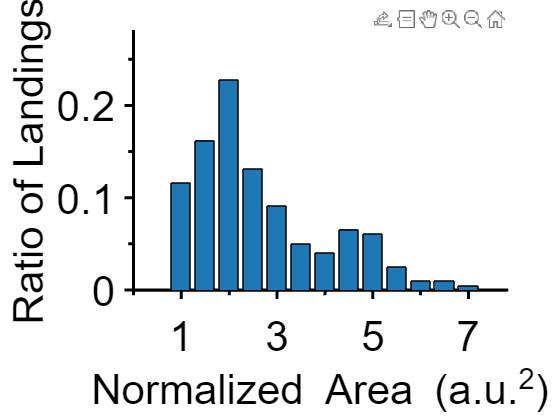

% Calculate the x-coordinates for the bars
x = edges(1:end-1);
bar_width = 0.8;

% Plot the histogram
figure;
hold on;

% Plot the bars on top of each other
bar(x, [ratio], bar_width);

xlim([0 7.8])
xticks(1:2:8)  % Major ticks

ylim([0 0.28])
yticks(0:0.1:0.5)

set(gca, 'Box', 'off', 'TickDir', 'out', 'TickLength', [.02 .02], ...
    'XMinorTick', 'on', 'YMinorTick', 'on', ...  % Turn off YMinorTick
    'XColor', 'k', 'YColor', 'k', 'LineWidth', 1, ...
    'FontSize', 28, 'linewidth', 2, 'FontWeight', 'normal', ...
    'YTickLabel', get(gca, 'YTickLabel'));


xlabel('Normalized Area (a.u.^2)', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28,'Color','black')
ylabel('Ratio of Landings', 'FontName', 'Arial', 'FontWeight', 'normal', 'FontSize', 28,'Color','black')

h = gca; % Get axis to modify
h.XAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.XAxis.MinorTickValues = 0:2:8; % Minor ticks which don't line up with majors

h.YAxis.MinorTick = 'on'; % Must turn on minor ticks if they are off
h.YAxis.MinorTickValues = 0.05:0.1:0.5; % Minor ticks which don't line up with majors

newcolors = {'#1f77b4', '#A2142F'};
colororder(newcolors)

%axis equal;  % Makes the x-axis and y-axis have the same length

